clear all
close all
addpath SVM-KM/

## training

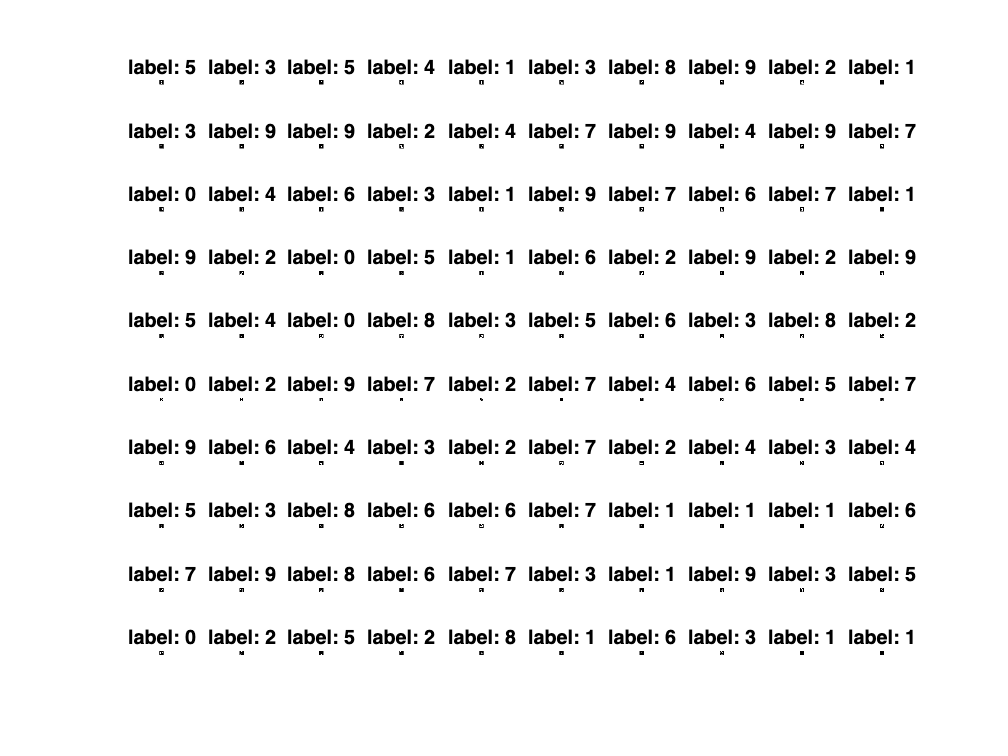

% Loading labels and examples of handwritten digits from MNIST Dataset
%Since they are too many of them, to make it usable for this practical we
%will be taking one out of many images (one out of 'sampling'). This is
%done by using the variable sampling>1
sampling=50;
images = loadMNISTImages('train-images',sampling);
labels = loadMNISTLabels('train-labels',sampling);

% For visualization purposes, we display the first 100 images
figure
for i=1:100
    
    % As you can notice by the size of the matrix image, each digit image
    % has been transform into a long feature vector to be fed in a machine
    % learning algorithm.
    
    %To visualise or recompose the image again, we need to revert that
    %process in its 28x28 image format
    Im = reshape(images(i,:),28,28);
    subplot(10,10,i), imshow(Im), title(['label: ',num2str(labels(i))])
    
end


% It is difficult for humans to visualise the full space of digits, since they have more than 700 dimension.
% In order to make it more human friendly and understand how difficult is
% the problem, i.e. how close or far away are the different classes, we can
% apply dimensionality reduction, which will give us the most relevant
% dimension to observe
[U,S,X_reduce] = pca(images,3);
imean=mean(images,1);
X_reduce=(images-ones(size(images,1),1)*imean)*U(:,1:3);

figure, hold on
colours= ['r.'; 'g.'; 'b.'; 'k.'; 'y.'; 'c.'; 'm.'; 'r+'; 'g+'; 'b+'; 'k+'; 'y+'; 'c+'; 'm+'];
count=0;
for i=min(labels):max(labels)
    count = count+1;
    indexes = find (labels == i);
    plot3(X_reduce(indexes,1),X_reduce(indexes,2),X_reduce(indexes,3),colours(count,:))
end

%Perform training
modelSVM = SVMtraining(images, labels);

building the distance matrix
in QP
      Cost     Delta Cost  #support  #up saturate
|  0.0000e+00 |   1.0000 |      1 |      0 |
|  0.0000e+00 |   0.0000 |      2 |      0 |
| -1.2147e+00 |   1.2147 |      3 |      0 |
| -1.8165e+00 |   0.4954 |      4 |      0 |
| -3.0818e+00 |   0.6965 |      5 |      0 |
| -3.9490e+00 |   0.2814 |      6 |      0 |
| -4.8052e+00 |   0.2168 |      7 |      0 |
| -5.5926e+00 |   0.1639 |      8 |      0 |
| -6.2969e+00 |   0.1259 |      9 |      0 |
| -7.0878e+00 |   0.1256 |     10 |      0 |
| -7.9967e+00 |   0.1282 |     11 |      0 |
| -8.8741e+00 |   0.1097 |     12 |      0 |
| -1.0033e+01 |   0.1306 |     13 |      0 |
| -1.1319e+01 |   0.1281 |     14 |      0 |
| -1.2176e+01 |   0.0758 |     15 |      0 |
| -1.3039e+01 |   0.0708 |     16 |      0 |
| -1.3854e+01 |   0.0625 |     17 |      0 |
| -1.4542e+01 |   0.0497 |     18 |      0 |
| -1.5336e+01 |   0.0546 |     19 |      0 |
      Cost     Delta Cost  #support  #up saturate
| -1.5924e

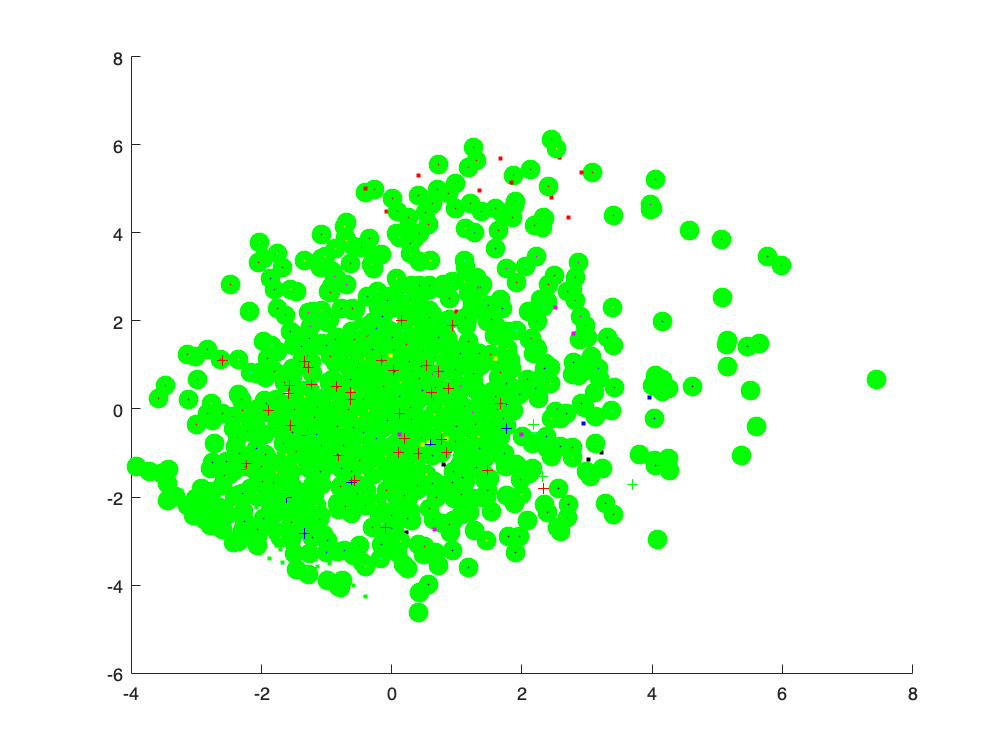


%After calculating the support vectors, we can draw them in the previous
%image

hold on
%transformation to the full image to the best 3 dimensions
imean=mean(images,1);
xsup_pca=(modelSVM.xsup-ones(size(modelSVM.xsup,1),1)*imean)*U(:,1:3);
% plot support vectors
h=plot3(xsup_pca(:,1),xsup_pca(:,2),xsup_pca(:,3),'go');
set(h,'lineWidth',5)

## testing

% Loading testing labels and testing examples of handwritten digits from MNIST Dataset
% It is very important that this images are different from the ones used in
% training or our results will not be reliable
images = loadMNISTImages('test-images',1);
labels = loadMNISTLabels('test-labels',1);
indexesZeros = find (labels == 0);
indexesOnes = find (labels == 1);

images= [images(indexesZeros,:); images(indexesOnes,:)];
labels= [labels(indexesZeros); labels(indexesOnes)];


for i=1:size(images,1)
    
    testnumber= images(i,:);
    
    classificationResult(i,1) = SVMTesting(testnumber,modelSVM);
    
end

## Evaluation

% Finally we compared the predicted classification from our mahcine
% learning algorithm against the real labelling of the esting image
comparison = (labels==classificationResult);

sum(comparison)

ans = 2065

length(comparison)

ans = 2115


%Accuracy is the most common metric. It is defiend as the numebr of
%correctly classified samples/ the total number of tested samples
Accuracy = double(sum(comparison)/length(comparison))

Accuracy = 0.9764

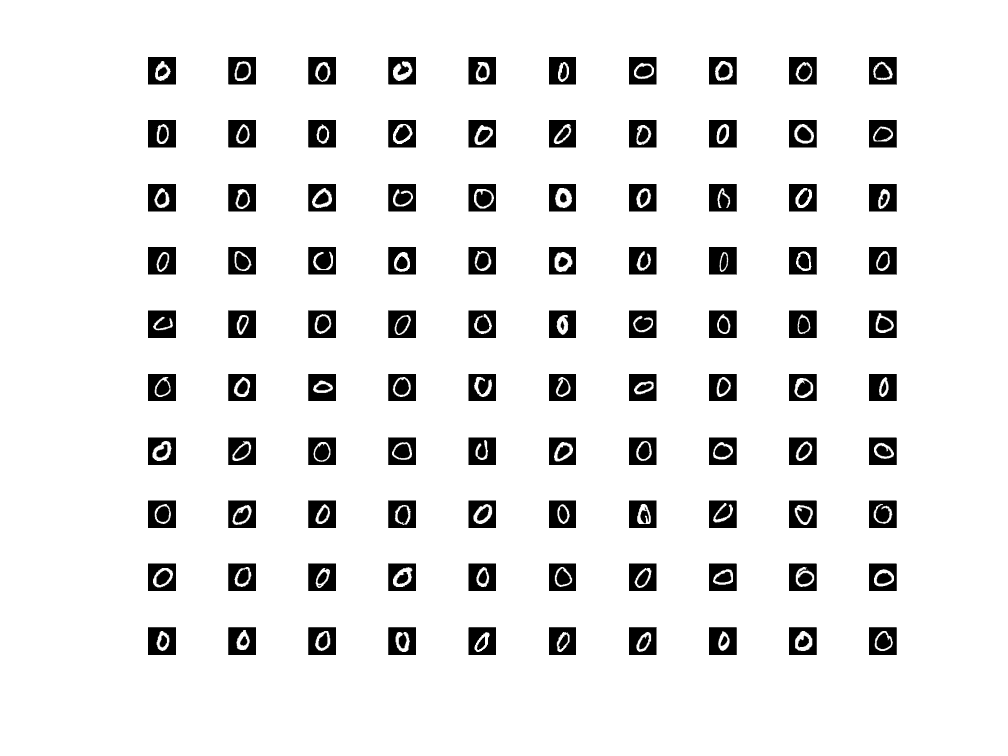



%We display 100 of the correctly classified images
figure
title('Correct Classification')
count=0;
i=1;
while (count<100)&&(i<=length(comparison))
    
    if comparison(i)
        count=count+1;
        subplot(10,10,count)
        Im = reshape(images(i,:),28,28);
        imshow(Im)
    end
    
    i=i+1;
    
end

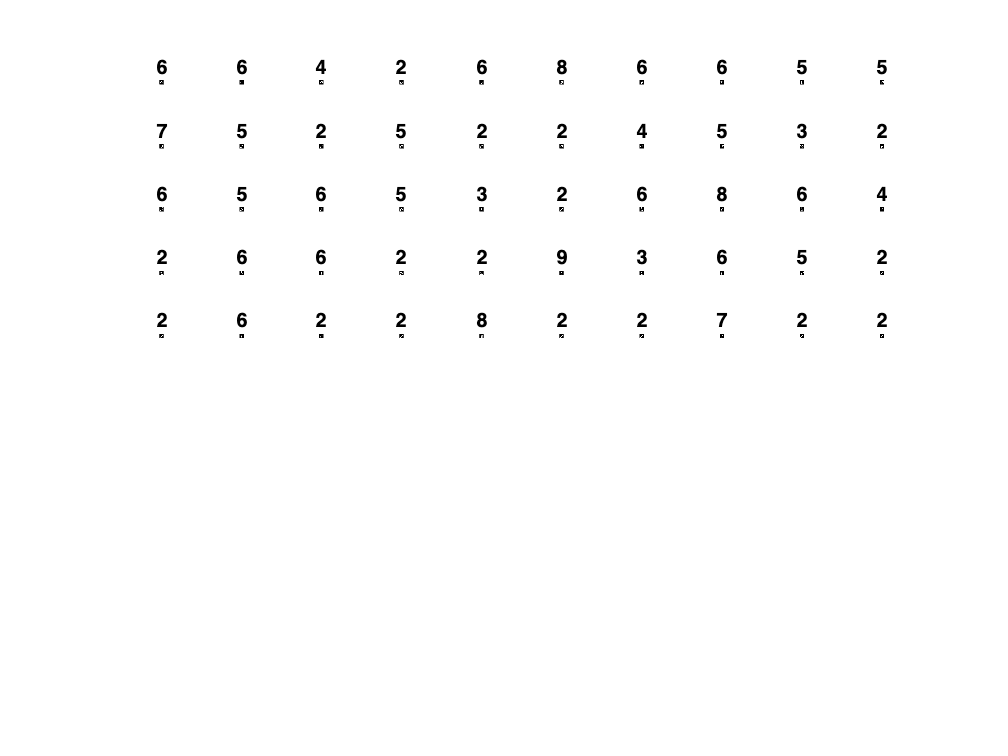



%We display 100 of the incorrectly classified images
figure
title('Wrong Classification')
count=0;
i=1;
while (count<100)&&(i<=length(comparison))
    
    if ~comparison(i)
        count=count+1;
        subplot(10,10,count)
        Im = reshape(images(i,:),28,28);
        imshow(Im)
        title(num2str(classificationResult(i)))
    end
    
    i=i+1;
    
end


save detectorModel modelSVM